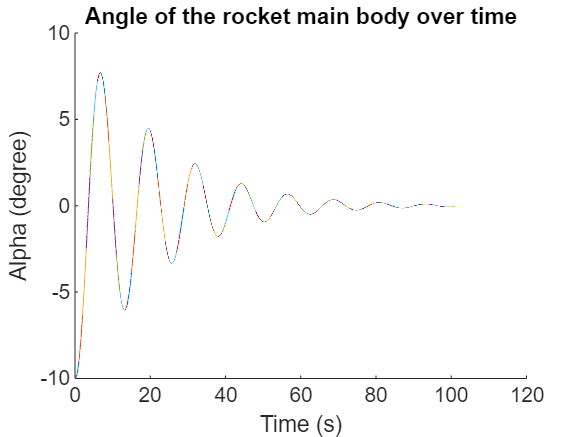

clear 
close all

c = 2;

Ki = 1;
Kp = 7;
Kd = 10;

alpha0_n = -10;
alpha1_n = 0;
theta_n1 = 0;
alpha_int = 0;
alpha_pid = alpha0_n;

%step size 
h = 1;
h1 = 0.01;
hlen = h/h1 + 1;

for t = 0:h:100
    u = Ki*alpha_int + Kp*alpha0_n + Kd*alpha1_n;
    theta_n1 = -u; 
    %Sign of theta
    if u < 0
        sgn = -1;
    else
        sgn = 1;
    end

    %Convert theta
    theta360 = rem(theta_n1,180);
    if abs(theta360) <= 90
        theta360;
    else
        if theta360 > 0
            theta360 = theta360 - 180;
        else
            theta360 = 180 + theta360;
        end
    end 
    theta_n1 = theta360;

    sin_theta = sind(theta_n1);

    %Set up system of diff eqs
    syms y(x)
    [V] = odeToVectorField(diff(y,2) == c*sin_theta);
    M = matlabFunction(V,'vars', {'x','Y'});

    %Solve system of eqs
    [t0, alpha_n1] = ode45(M,0:h1:h,[alpha0_n alpha1_n]);
    alpha0 = alpha_n1(:,1);
    alpha1 = alpha_n1(:,2);
    
    alpha0_d = alpha0;
    
    %Convert array alpha0
    for j = 1:hlen

        if alpha0(j) < 0
        sgn_alpha = -1;
        else
        sgn_alpha = 1;
        end

        alpha360 = rem(alpha0(j),180);
        if abs(alpha360) <= 90
            alpha360;
        else
            if alpha360 > 0
                alpha360 = alpha360 - 180;
            else
                alpha360 = 180 + alpha360;
            end
        end
        alpha0_d(j) = alpha360;
    end

    %Inspect
    t;
    theta_n1;
    sin_theta;
    alpha0_d(hlen);

    time = t0+t;

    hold on
    plot(time, alpha0_d)
    title('Angle of the rocket main body over time')
    xlabel('Time (s)')
    ylabel('Alpha (degree)')

    alpha0_n = alpha0(hlen);
    alpha1_n = alpha1(hlen);
    alpha_int = alpha_int + alpha0_n;

end
hold off